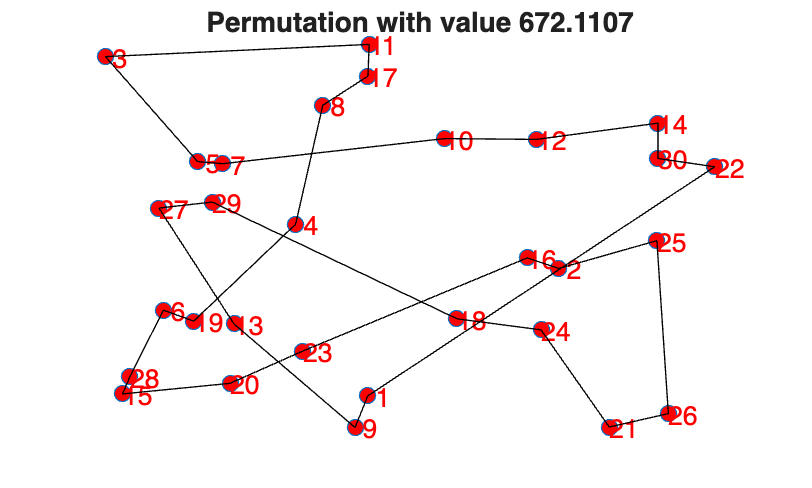

clear;clc;clf;
load ex12.mat

nr_cities = 30;
pop_size = 40;        
n_bits = 30;           
n_gen = 1000;       
pc = 0.8;              
pm = 0.05;             



[~, indices] = sort(rand(pop_size, 29), 2);
pop = [ones(pop_size, 1), indices + 1];
gen_fitness = Inf*ones(50,1);


for i_gen = 1:n_gen
    
    fit = Inf*ones(pop_size,1);

    for pop_idx = 1:pop_size
        fit(pop_idx) = eval_perm(pop(pop_idx,:),dist_matrix,nr_cities);
    end
    
    [min_fit, idx_best] = min(fit);
    best_so_far = pop(idx_best,:);
    gen_fitness(i_gen) = min_fit;
    
    % --- SELECTION (Roulette Wheel) ---
    new_pop = zeros(size(pop));
     
    [sorted_fit, sorted_ids] = sort(fit, 'ascend');
    prob = (pop_size:-1:1) / sum(pop_size:-1:1);
    cum_prob = cumsum(prob);
    
    selected_indices = zeros(pop_size, 1);
    for k = 1:pop_size
        r = rand();
        rank_idx = find(cum_prob >= r, 1, 'first');

        selected_indices(k) = sorted_ids(rank_idx);
    end
    mating_pool = pop(selected_indices, :);

    % --- CROSSOVER (Single-point Crossover) ---
    for k = 1:2:pop_size
        p1 = mating_pool(k, :);
        p2 = mating_pool(k+1, :);
        
        if rand() < pc
            swap_points = randi([2,n_bits],2,1);
    
            p1_new = pmx_one_child(p1, p2, swap_points(1), swap_points(2));
            p2_new = pmx_one_child(p2, p1, swap_points(1), swap_points(2));  % Prehodené!

            new_pop(k, :) = p1_new;
            new_pop(k+1, :) = p2_new;
        else

            new_pop(k, :) = p1;
            new_pop(k+1, :) = p2;
        end
    end
    
    % --- MUTATION (swap) ---
    for i_pop = 2:pop_size
        if rand() < pm
            swap_idxs = randi([2,n_bits],2,1);
            new_pop(i_pop, [swap_idxs(1), swap_idxs(2)]) = ...
    new_pop(i_pop, [swap_idxs(2), swap_idxs(1)]);
        end
    end

    pop = new_pop;
end
hold on;
scatter(positions(:,1),positions(:,2),MarkerFaceColor='red');
text(positions(:,1),positions(:,2),num2str((1:nr_cities)'),color='red');
plot([positions(best_so_far,1);positions(1,1)],[positions(best_so_far,2);positions(1,2)],'k-');
axis off;
title("Permutation with value " + num2str(gen_fitness(end)))

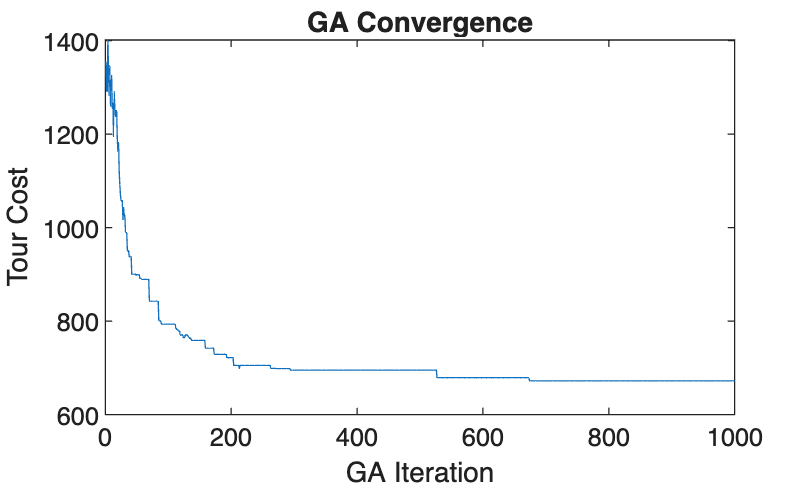


figure;
plot(1:n_gen, gen_fitness)
xlabel('GA Iteration');
ylabel('Tour Cost');
title('GA Convergence');


%evaluation function
function val = eval_perm(perm,dist_matrix,nr_cities)
    val = 0;
    for i=1:nr_cities-1
        cur_city = perm(i);
        next_city = perm(i+1);
        val = val + dist_matrix(cur_city,next_city);
    end
    val = val + dist_matrix(perm(nr_cities),perm(1));
end

function child = pmx_one_child(p1, p2, i, j)
    if i > j
        temp = i;
        i = j;
        j = temp;
    end

    n = length(p1);
    child = zeros(1, n);

    child(i:j) = p1(i:j);

    for k = i:j
        gene = p2(k);
        if ~ismember(gene, child(i:j))
            pos = k;
            while pos >= i && pos <= j
          
                mapped = p1(pos);
                pos = find(p2 == mapped);
            end
            child(pos) = gene;
        end
    end
    
    for k = 1:n
        if child(k) == 0
            child(k) = p2(k);
        end
    end
end
